## REDO exercise of 15-04

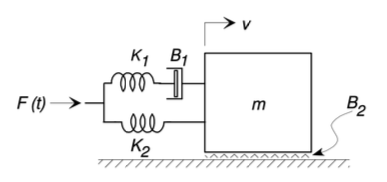

clear variables
close all

% definition of symbolic variables
syms t v_m(t) v_S1(t) v_S2(t) v_D1(t) v_D2(t) v_F(t) 
syms F_m(t) F_S1(t) F_S2(t) F_D1(t) F_D2(t) F_F(t)
% define vector 
%syms alpha tau
% definition of vetcor of through variables
tau = [ 
  F_m(t) 
  F_D1(t)
  F_S1(t)
  F_D2(t)
  F_S2(t)
  F_F(t)
]

$$tau = \left(\begin{array}{c} F_{m}\left(t\right)\\ F_{\mathrm{D1}}\left(t\right)\\ F_{\mathrm{S1}}\left(t\right)\\ F_{\mathrm{D2}}\left(t\right)\\ F_{\mathrm{S2}}\left(t\right)\\ F_{F}\left(t\right) \end{array}\right)$$

% definition of vector of across variables
alpha = [ 
  v_m(t) 
  v_D1(t)
  v_S1(t)
  v_D2(t)
  v_S2(t)
  v_F(t)
]

$$alpha = \left(\begin{array}{c} v_{m}\left(t\right)\\ v_{\mathrm{D1}}\left(t\right)\\ v_{\mathrm{S1}}\left(t\right)\\ v_{\mathrm{D2}}\left(t\right)\\ v_{\mathrm{S2}}\left(t\right)\\ v_{F}\left(t\right) \end{array}\right)$$


% definition of problem dimensions
ne = 6; % number of elements
nb = 3; % number of branches
nc = ne-nb; % number of chords/links

Incidence matrix

syms IM;
IM = [0, 0, -1, 0, -1, 1;
      0, -1, 1, 0, 0, 0;
      -1, 1, 0, -1, 1, 0;
      1, 0, 0, 0, 1, -1]

IM =      0     0    -1     0    -1     1
     0    -1     1     0     0     0
    -1     1     0    -1     1     0
     1     0     0     0     1    -1



% define it as symbolic
IMs = sym(IM);
IMr = IMs(1:nc, 1:ne);

% Finding echelon form -> Af
Af = rref(IMr)

$$Af = \left(\begin{array}{cccccc} 1 & 0 & 0 & 1 & 0 & -1\\ 0 & 1 & 0 & 0 & 1 & -1\\ 0 & 0 & 1 & 0 & 1 & -1 \end{array}\right)$$

Equations for primary and secondary through variables

Ib = Af(1:nb, 1:nb)

$$Ib = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Ac = Af(1:nb, nb+1:ne)

$$Ac = \left(\begin{array}{ccc} 1 & 0 & -1\\ 0 & 1 & -1\\ 0 & 1 & -1 \end{array}\right)$$

#### Node equations

node_eqns = tau(1:nb) == -Ac*tau(nb+1:ne)

$$node\_eqns = \left(\begin{array}{c} F_{m}\left(t\right)=F_{F}\left(t\right)-F_{\mathrm{D2}}\left(t\right)\\ F_{\mathrm{D1}}\left(t\right)=F_{F}\left(t\right)-F_{\mathrm{S2}}\left(t\right)\\ F_{\mathrm{S1}}\left(t\right)=F_{F}\left(t\right)-F_{\mathrm{S2}}\left(t\right) \end{array}\right)$$

#### Loop equations

Bf = null(Af)'

$$Bf = \left(\begin{array}{cccccc} -1 & 0 & 0 & 1 & 0 & 0\\ 0 & -1 & -1 & 0 & 1 & 0\\ 1 & 1 & 1 & 0 & 0 & 1 \end{array}\right)$$

Af*Bf'  % <--- check conservation of energy

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

Bb = -Ac'

$$Bb = \left(\begin{array}{ccc} -1 & 0 & 0\\ 0 & -1 & -1\\ 1 & 1 & 1 \end{array}\right)$$

loop_eqns = alpha(nb+1:ne) == -Bb*alpha(1:nb)

$$loop\_eqns = \left(\begin{array}{c} v_{\mathrm{D2}}\left(t\right)=v_{m}\left(t\right)\\ v_{\mathrm{S2}}\left(t\right)=v_{\mathrm{D1}}\left(t\right)+v_{\mathrm{S1}}\left(t\right)\\ v_{F}\left(t\right)=-v_{\mathrm{D1}}\left(t\right)-v_{\mathrm{S1}}\left(t\right)-v_{m}\left(t\right) \end{array}\right)$$

#### Constitutive equations

% Mass element
syms m ;%s_m(t)
const_eqn_m = [diff(v_m(t),t) == F_m(t)/m]

$$const\_eqn\_m = \frac{\partial }{\partial t}v_{m}\left(t\right)=\frac{F_{m}\left(t\right)}{m}$$

               %diff(s_m(t),t) == v_m(t)]

% Damper D1
syms K_D1 ;%s_D1(t)
const_eqn_D1 = [F_D1(t) == K_D1*v_D1(t)]

$$const\_eqn\_D1 = F_{\mathrm{D1}}\left(t\right)=K_{\mathrm{D1}}\,v_{\mathrm{D1}}\left(t\right)$$

               %diff(s_D1(t),t) == v_D1(t)]

% Spring KS1
% here we need to add the internal state s_S1(t): spring deformation
syms K_S1 s_S1(t);
const_eqn_S1 = [F_S1(t) == K_S1*s_S1(t)
                diff(s_S1(t),t) == v_S1(t)]

$$const\_eqn\_S1 = \left(\begin{array}{c} F_{\mathrm{S1}}\left(t\right)=K_{\mathrm{S1}}\,s_{\mathrm{S1}}\left(t\right)\\ \frac{\partial }{\partial t}s_{\mathrm{S1}}\left(t\right)=v_{\mathrm{S1}}\left(t\right) \end{array}\right)$$


% Damper D2
syms K_D2 ;%s_D2(t)
const_eqn_D2 = [F_D2(t) == K_D2*v_D2(t)]

$$const\_eqn\_D2 = F_{\mathrm{D2}}\left(t\right)=K_{\mathrm{D2}}\,v_{\mathrm{D2}}\left(t\right)$$

               %diff(s_D1(t),t) == v_D1(t)]

% Force source
syms A f;
const_eqn_F = [F_F(t) == A*sin(2*pi*f*t)]

$$const\_eqn\_F = F_{F}\left(t\right)=A\,\sin\left(2\,\pi \,f\,t\right)$$


% Spring KS2
% here we need to add the internal state s_S2(t): spring deformation
syms K_S2 s_S2(t);
const_eqn_S2 = [F_S2(t) == K_S2*s_S2(t)
                diff(s_S2(t),t) == v_S2(t)]

$$const\_eqn\_S2 = \left(\begin{array}{c} F_{\mathrm{S2}}\left(t\right)=K_{\mathrm{S2}}\,s_{\mathrm{S2}}\left(t\right)\\ \frac{\partial }{\partial t}s_{\mathrm{S2}}\left(t\right)=v_{\mathrm{S2}}\left(t\right) \end{array}\right)$$

Deriving ODE for mass acceleration

tmp0 = subs(const_eqn_m, lhs(node_eqns(1)), rhs(node_eqns(1)))

$$tmp0 = \frac{\partial }{\partial t}v_{m}\left(t\right)=-\frac{F_{\mathrm{D2}}\left(t\right)-F_{F}\left(t\right)}{m}$$

tmp0 = subs(tmp0, lhs(const_eqn_D2), rhs(const_eqn_D2))

$$tmp0 = \frac{\partial }{\partial t}v_{m}\left(t\right)=\frac{F_{F}\left(t\right)-K_{\mathrm{D2}}\,v_{\mathrm{D2}}\left(t\right)}{m}$$

tmp0 = subs(tmp0, lhs(const_eqn_F), rhs(const_eqn_F))

$$tmp0 = \frac{\partial }{\partial t}v_{m}\left(t\right)=-\frac{K_{\mathrm{D2}}\,v_{\mathrm{D2}}\left(t\right)-A\,\sin\left(2\,\pi \,f\,t\right)}{m}$$

tmp0 = subs(tmp0, lhs(loop_eqns(1)), rhs(loop_eqns(1)))

$$tmp0 = \frac{\partial }{\partial t}v_{m}\left(t\right)=-\frac{K_{\mathrm{D2}}\,v_{m}\left(t\right)-A\,\sin\left(2\,\pi \,f\,t\right)}{m}$$


mass_ode = tmp0

$$mass\_ode = \frac{\partial }{\partial t}v_{m}\left(t\right)=-\frac{K_{\mathrm{D2}}\,v_{m}\left(t\right)-A\,\sin\left(2\,\pi \,f\,t\right)}{m}$$


V = odeToVectorField(mass_ode);
symvar(V);
RHS_ode = matlabFunction(V,'vars',{'t','Y',m,K_D2,A,f} ,'File','ode_mass_rhs');

data_m  = 1

data_m = 1

data_A = 1

data_A = 1

data_f = 1

data_f = 1

data_K_D2 = 1

data_K_D2 = 1

data_K_D1 = 2

data_K_D1 = 2

data_K_S1 = 100

data_K_S1 = 100

data_K_S2 = 5

data_K_S2 = 5


F = @(t,Y) ode_mass_rhs(t,Y,data_m,data_K_D2,data_A,data_f);
% %M = @(t,Y) M(t,Y,);

% Initial conditions for differential system
v_m0 = 0.0;

Tf = 10; % interval of integration

%Specify consistent initial conditions for the ode system
initConditions = [v_m0 ];

F(0,initConditions)

ans = 0

sol = ode45(@(t,Y)F(t,Y),[0 Tf],initConditions)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.2686 0.5372 0.8366 1.0579 1.2792 1.6023 1.8755 2.1688 2.4484 2.7326 2.9836 3.2346 3.4642 3.6938 3.9609 4.2280 4.4832 4.7385 4.9480 5.1575 5.4829 5.7616 6.0536 6.3456 6.6608 6.9347 7.2151 7.4818 7.7486 7.9442 8.1397 … ] (1×39 double)
          y: [0 0.1613 0.2360 -0.0342 -0.0824 0.0958 0.1407 -0.1037 -0.0365 0.1684 0.0024 -0.1491 0.0157 0.1617 0.0344 -0.1536 0.0053 0.1587 -0.0121 -0.1538 -0.0637 0.1576 -0.0355 -0.1380 0.1084 0.0618 -0.1520 -0.0095 0.1571 -0.0233 … ] (1×39 double)
      stats: [1×1 struct]
      idata: [1×1 struct]


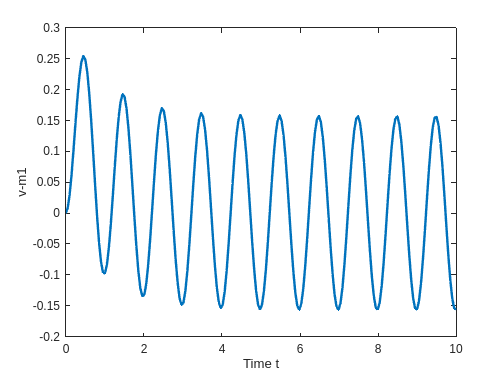


tt = linspace(0,Tf,200);
% with command deval() we evaluate differential equation solution structure
% over the values of x and for the component 1
sol_v1 = deval(sol,tt,1);

figure()
plot(tt,sol_v1,'Linewidth',2)
xlabel('Time t')
ylabel('v-m1')